Es = 1; 
N = 1e5;
p1 = 0.5;


function bit_vec = BitVec(Nbit,pbit)
    bit_vec = rand(1,Nbit) < pbit ;
end

function sym_vec = QAM4SymVec(bit_vec,Es)
    L = length(bit_vec);
    sym_vec = zeros(1,L/2) ;
    for i = 1 : L/2
        a = bit_vec(2*i-1);
        b = bit_vec(2*i);
        s = (-1)^a + (-1)^b * 1i ;
        sym_vec(i) = s / abs(s) * sqrt(Es); 
    end 
end


function [sym_vec_tx,yvec] = QAM4_Rec(SNRb, Es, Nbit, pbit)
    Eb = Es / 2;
    N0 = Eb / SNRb;
    
    B = BitVec(Nbit,pbit);
    sym_vec_tx = QAM4SymVec(B,Es);
    Ns = length(sym_vec_tx);

    CSCN = randn(1,Ns) + randn(1,Ns) * 1i;
    yvec = sym_vec_tx + CSCN * sqrt(N0/2);
end 


function svecdec=QAM4_SymMAPDec(yvec, SNRb, Es, pbit)
    svecdec = zeros(1,length(yvec));
    P = [ (1-pbit)^2 , (1-pbit)*pbit , (pbit)^2 , (1-pbit)*pbit ];
    
    Eb = Es / 2;
    N0 = Eb / SNRb; 
    
    % FIX: Swapped P(2)/P(3) to P(3)/P(2) to align 'Left/Right' ratio 
    % with 'Bottom/Top' logic used in bias_Im
    bias_Re = N0/2 * log(P(3)/P(2)); 
    bias_Im = N0/2 * log(P(2)/P(1));

    for i = 1 : length(yvec)
        y = yvec(i);
        a = real(y);
        b = imag(y);
        
        s_raw = (-1)^((a >= bias_Re)+1) + (-1)^((b >= bias_Im)+1) * 1i;
        
        svecdec(i) = s_raw / abs(s_raw) * sqrt(Es);
    end
end


function ser=CompSER(sym_vec_tx,svecdec)
    ser = 1 - sum(abs(sym_vec_tx - svecdec) < 1e-5) / length(sym_vec_tx);
end


SNR_s = -6 : 6;
SER = zeros(1,length(SNR_s));

for i = 1 : length(SNR_s)
    SNRb_DB = SNR_s(i);
    SNRb = 10^(SNRb_DB/10);
    [S,Y] = QAM4_Rec(SNRb, Es, N, p1);
    S_dec = QAM4_SymMAPDec(Y, SNRb, Es, p1);
    
    ser = CompSER(S,S_dec);
    SER(i) = ser;
end 


disp('SNR (dB):');

SNR (dB):


disp(SNR_s);

    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6



disp('SER:');

SER:


disp(SER);

    0.4247    0.3793    0.3384    0.2951    0.2449    0.1961    0.1510    0.1104    0.0745    0.0459    0.0238    0.0117    0.0047



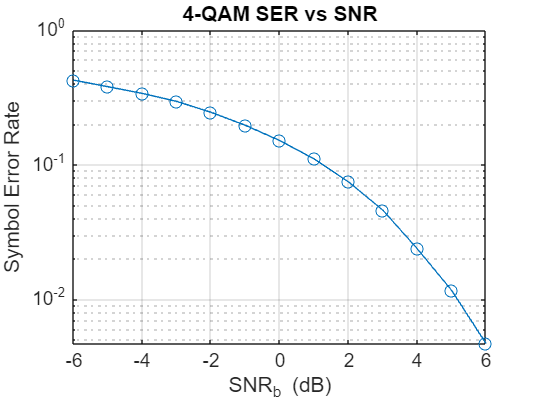

figure
semilogy(SNR_s, SER, '-o');
grid on;
title('4-QAM SER vs SNR');
xlabel('SNR_b (dB)');
ylabel('Symbol Error Rate');

p1_s = 0.01: 0.01 : 0.99;
SER = zeros(1,length(p1_s));
SNRb_DB = -3;

for i = 1 : length(p1_s)
    p1 = p1_s(i);
    SNRb = 10^(SNRb_DB/10);
    [S,Y] = QAM4_Rec(SNRb, Es, N, p1);
    S_dec = QAM4_SymMAPDec(Y, SNRb, Es, p1);
    
    ser = CompSER(S,S_dec);
    SER(i) = ser;
end 


disp('p1:');

p1:


disp(p1_s);

    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900    0.6000    0.6100    0.6200    0.6300    0.6400    0.6500    0.6600    0.6700    0.6800    0.6900    0.7000    0.7100    0.7200    0.7300    0.7400    0.7500    0.7600    0.7700    0.7800    0.7900    0.8000    0.8100    0.8200    0.8300    0.8400    0.8500    0.8600    0.8700    0.8800    0.8900    0.9000    0.9100    0.9200    0.9300    0.9400    0.9500    0.9600    0.9700    0.9800    0.9900



disp('SER:');

SER:


disp(SER);

    0.0201    0.0379    0.0543    0.0716    0.0862    0.0989    0.1110    0.1267    0.1344    0.1427    0.1571    0.1664    0.1739    0.1848    0.1887    0.1958    0.2014    0.2091    0.2163    0.2244    0.2265    0.2308    0.2395    0.2416    0.2435    0.2469    0.2530    0.2528    0.2550    0.2687    0.2645    0.2686    0.2724    0.2686    0.2726    0.2786    0.2803    0.2854    0.2836    0.2845    0.2886    0.2912    0.2876    0.2886    0.2920    0.2870    0.2909    0.2929    0.2880    0.2911    0.2930    0.2896    0.2904    0.2918    0.2904    0.2932    0.2929    0.2834    0.2873    0.2855    0.2828    0.2815    0.2833    0.2778    0.2717    0.2739    0.2722    0.2694    0.2680    0.2619    0.2603    0.2596    0.2521    0.2492    0.2483    0.2401    0.2351    0.2303    0.2247    0.2229    0.2169    0.2079    0.2048    0.1951    0.1877    0.1772    0.1746    0.1632    0.1531    0.1445    0.1359    0.1220    0.1108    0.0981    0.0870    0.0698    0.0546    0.0373    0.0185



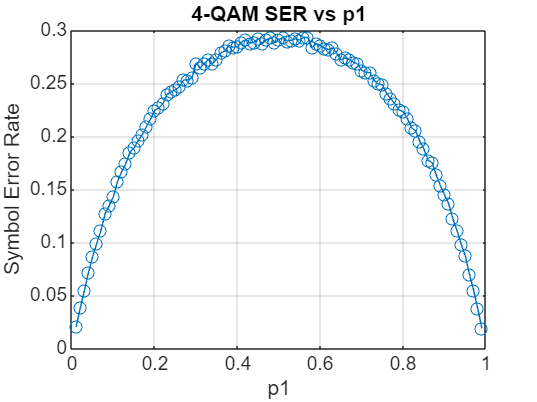

figure
plot(p1_s, SER, '-o');
grid on;
title('4-QAM SER vs p1');
xlabel('p1');
ylabel('Symbol Error Rate');

Es = 1; 
Nsym = 1e5;

function sym_vec = QAM8SymVec(Nsym, Es)
    sqEs = sqrt(Es);
    
    S0 =  sqEs + 1i*(sqEs/2);
    S1 =  sqEs - 1i*(sqEs/2);
    S2 =  (sqEs/2) + 1i*0;
    S3 =  0 + 1i*(sqEs/2);
    S4 =  0 - 1i*(sqEs/2);
    S5 = -(sqEs/2) + 1i*0;
    S6 = -sqEs + 1i*(sqEs/2);
    S7 = -sqEs - 1i*(sqEs/2);
    
    Constellation = [S0, S1, S2, S3, S4, S5, S6, S7];
    
    indices = randi([1, 8], 1, Nsym);
    sym_vec = Constellation(indices);
end

function yvec = QAM8_Rec(sym_vec8, SNRb, Es)
    E_avg = 0.75 * Es;
    Eb = E_avg / 3;
    N0 = Eb / SNRb;
    
    Ns = length(sym_vec8);
    noise = (randn(1, Ns) + 1i*randn(1, Ns)) * sqrt(N0/2);
    yvec = sym_vec8 + noise;
end 

function svecdec = QAM8_SymMAPDec(yvec, Es)
    sqEs = sqrt(Es);
    Constellation = [ ...
         (sqEs + 1i*sqEs/2), ...
         (sqEs - 1i*sqEs/2), ...
         (sqEs/2 + 1i*0), ...
         (0 + 1i*sqEs/2), ...
         (0 - 1i*sqEs/2), ...
         (-sqEs/2 + 1i*0), ...
         (-sqEs + 1i*sqEs/2), ...
         (-sqEs - 1i*sqEs/2) ];
         
    svecdec = zeros(1, length(yvec));
    
    for i = 1 : length(yvec)
        y = yvec(i);
        [~, idx] = min(abs(y - Constellation).^2);
        svecdec(i) = Constellation(idx);
    end
end

SNR_dB = -25 : 1 : 0;
SER_Sim = zeros(1, length(SNR_dB));
SER_Theory = zeros(1, length(SNR_dB));

for i = 1 : length(SNR_dB)
    snr_db_val = SNR_dB(i);
    SNRb = 10^(snr_db_val/10);
    
    S = QAM8SymVec(Nsym, Es);
    Y = QAM8_Rec(S, SNRb, Es);
    S_dec = QAM8_SymMAPDec(Y, Es);
    
    SER_Sim(i) = CompSER(S, S_dec);
    SER_Theory(i) = 3 * 0.5 * erfc(sqrt(SNRb)/sqrt(2));
end 


disp('SNR (dB):'); disp(SNR_dB);

SNR (dB):
   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0



disp('SER Sim:'); disp(SER_Sim);

SER Sim:
    0.8513    0.8477    0.8435    0.8387    0.8336    0.8294    0.8223    0.8171    0.8076    0.7993    0.7913    0.7798    0.7670    0.7512    0.7337    0.7150    0.6913    0.6671    0.6394    0.6058    0.5679    0.5276    0.4853    0.4365    0.3813    0.3258



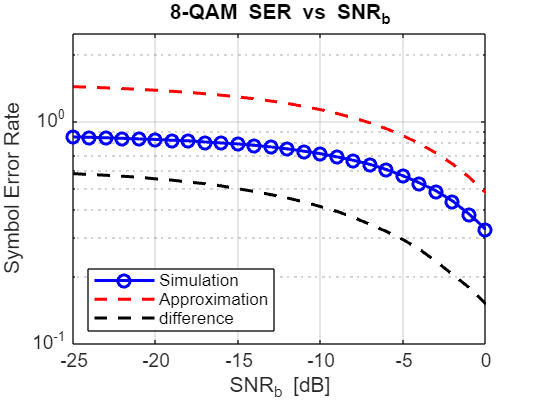


figure;
semilogy(SNR_dB, SER_Sim, 'bo-', 'LineWidth', 1.5);
hold on;
semilogy(SNR_dB, SER_Theory, 'r--', 'LineWidth', 1.5);
semilogy(SNR_dB, (SER_Theory - SER_Sim), 'black--', 'LineWidth', 1.5);
grid on;
title('8-QAM SER vs SNR_b');
xlabel('SNR_b [dB]');
ylabel('Symbol Error Rate');
legend('Simulation', 'Approximation','difference', 'Location', 'southwest');
axis([-25 0 1e-1 2.5]);

Nsc = 128;
Ncp = 8;

function s = QAM4_Mapper(bits)
    b = bits(1)*2 + bits(2);
    scale = 1/sqrt(2);
    switch b
        case 0 % 00
            s = (1 + 1i) * scale;
        case 1 % 01
            s = (1 - 1i) * scale;
        case 3 % 11
            s = (-1 - 1i) * scale;
        case 2 % 10
            s = (-1 + 1i) * scale;
    end
end
function dec_bits = QAM4_Decode(sym_est_vec)
    L = length(sym_est_vec);
    dec_bits = zeros(1, 2*L);
    for i = 1:L
        re = real(sym_est_vec(i));
        im = imag(sym_est_vec(i));
        if re >= 0 && im >= 0
            b = [0 0];
        elseif re >= 0 && im < 0
            b = [0 1];
        elseif re < 0 && im >= 0
            b = [1 0];
        else
            b = [1 1];
        end
        dec_bits(2*i-1 : 2*i) = b;
    end
end


function s = QAM8_Mapper(bits)
    Es = 1;
    sqEs = sqrt(Es);
    
    dec = bits(1)*4 + bits(2)*2 + bits(3);
    
    switch dec
        case 0 % 000 -> S3
            s = 0 + 1i*(sqEs/2);
        case 1 % 001 -> S0
            s = sqEs + 1i*(sqEs/2);
        case 3 % 011 -> S1
            s = sqEs - 1i*(sqEs/2);
        case 2 % 010 -> S4
            s = 0 - 1i*(sqEs/2);
        case 6 % 110 -> S7
            s = -sqEs - 1i*(sqEs/2);
        case 7 % 111 -> S6
            s = -sqEs + 1i*(sqEs/2);
        case 5 % 101 -> S5
            s = -(sqEs/2) + 1i*0;
        case 4 % 100 -> S2
            s = (sqEs/2) + 1i*0;
    end
end

function dec_bits = QAM8_Decode(sym_est_vec)
    Es = 1; sqEs = sqrt(Es);
    S = [ (0+1i*sqEs/2), (sqEs+1i*sqEs/2), (sqEs-1i*sqEs/2), (0-1i*sqEs/2), ...
          (-sqEs-1i*sqEs/2), (-sqEs+1i*sqEs/2), (-sqEs/2), (sqEs/2) ];
    % 1:000, 2:001, 3:011, 4:010, 5:110, 6:111, 7:101, 8:100
    BitsMap = [0 0 0; 0 0 1; 0 1 1; 0 1 0; 1 1 0; 1 1 1; 1 0 1; 1 0 0];
    
    L = length(sym_est_vec);
    dec_bits = zeros(1, 3*L);
    
    for i = 1:L
        val = sym_est_vec(i);
        [~, idx] = min(abs(val - S).^2); 
        dec_bits(3*i-2 : 3*i) = BitsMap(idx, :);
    end
end

% --- 1. OFDM Modulator (Item 2.2.1) ---
function xofdm = OFDM_Mod(bit_stream, Nsc, Ncp, constellation)
    if strcmp(constellation, 'BPSK')
        M_bits = 1;
        Es = 1; 
        map_func = @(b) (2*b - 1) * sqrt(Es); 
        
    elseif strcmp(constellation, '4QAM')
        M_bits = 2;
        Es = 1;
        map_func = @QAM4_Mapper;
        
    elseif strcmp(constellation, '8QAM')
        M_bits = 3;
        Es = 1;
        map_func = @QAM8_Mapper;
    else
        error('Unknown constellation');
    end
    bits_per_ofdm = Nsc * M_bits;
    L = length(bit_stream);
    remainder = mod(L, bits_per_ofdm);

    if remainder ~= 0
        padding = randi([0 1], 1, bits_per_ofdm - remainder);
        bit_stream = [bit_stream, padding];
    end
    
    num_bits = length(bit_stream);
    num_syms = num_bits / M_bits;     % Number of constellation symbols
    num_ofdm = num_syms / Nsc;        % Number of OFDM symbols (m)
    
    const_symbols = zeros(1, num_syms);
    for i = 1:num_syms
        b_idx = (i-1)*M_bits + 1;
        bits = bit_stream(b_idx : b_idx+M_bits-1);
        const_symbols(i) = map_func(bits);
    end

    sym_matrix = reshape(const_symbols, Nsc, num_ofdm).'; 
    
    sym_matrix_T = sym_matrix.'; % Size Nsc x m
    time_matrix_T = ifft(sym_matrix_T) * sqrt(Nsc) ;% Nsc x m
    
    cp_part = time_matrix_T(end-Ncp+1:end, :);
    ofdm_syms_T = [cp_part; time_matrix_T]; % Size (Nsc+Ncp) x m
    
    xofdm = ofdm_syms_T(:).'; 
end



% --- 2. Wireless Channel (Item 2.2.2) ---
function [r1ofdm, r2ofdm] = Wireless_Channel(xofdm, N0)
    % Constants
    omega0 = 2 * pi * sqrt(2);
    
    % Channel 1 Def
    a1_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5];
    a1 = (1/10.2424) * a1_vals;
    L1 = length(a1);
    h1 = zeros(1, L1);
    for n = 0:L1-1
        h1(n+1) = a1(n+1) * exp(1i * omega0 * n);
    end
    
    % Channel 2 Def
    a2_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
    a2 = (1/11.4648) * a2_vals;
    L2 = length(a2);
    h2 = zeros(1, L2);
    for n = 0:L2-1
        h2(n+1) = a2(n+1) * exp(1i * omega0 * n);
    end
    
    % Apply Convolutions
    r1_conv = conv(xofdm, h1);
    r2_conv = conv(xofdm, h2);
    
    % Truncate to length of input
    Lx = length(xofdm);
    r1_trunc = r1_conv(1:Lx);
    r2_trunc = r2_conv(1:Lx);
    
    % Generate Noise
    % CN(0, N0) -> Real/Imag parts have var N0/2
    noise = (randn(1, Lx) + 1i*randn(1, Lx)) * sqrt(N0/2);
    
    % Add Noise
    r1ofdm = r1_trunc + noise;
    r2ofdm = r2_trunc + noise;
end

% --- 3. OFDM Demodulator (Item 2.2.3) ---
function dec_bits = OFDM_Demod(rvec, Nsc, Ncp, constellation, Channel)
    omega0 = 2 * pi * sqrt(2);
    if Channel == 1
        a_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5];
        norm_fac = 1/10.2424;
    else
        a_vals = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
        norm_fac = 1/11.4648;
    end

    a = norm_fac * a_vals;
    L = length(a);
    h = zeros(1, L);

    for n = 0:L-1
        h(n+1) = a(n+1) * exp(1i * omega0 * n);
    end
    H_k = fft(h, Nsc);
    
    Nsym = Nsc + Ncp;
    num_samples = length(rvec);
    m = floor(num_samples / Nsym);
    r_matrix = reshape(rvec(1:m*Nsym), Nsym, m);
    r_no_cp = r_matrix(Ncp+1:end, :); % Size Nsc x m
    y_freq = fft(r_no_cp) / sqrt(Nsc); % Size Nsc x m
    H_k_mat = repmat(H_k.', 1, m); % Ensure H_k is column
    sym_est_mat = y_freq ./ H_k_mat;
    
    % Serialize to vector of symbols
    % sym_est_vec = sym_est_mat.'; % Transpose to get row-by-row
    % sym_est_vec = sym_est_vec(:).';
    sym_est_vec = sym_est_mat(:).';
    
    % 6. Demap / Decode Bits
    dec_bits = [];
    if strcmp(constellation, 'BPSK')
        dec_bits = real(sym_est_vec) > 0;
    elseif strcmp(constellation, '4QAM')
        dec_bits = QAM4_Decode(sym_est_vec);
    elseif strcmp(constellation, '8QAM')
        dec_bits = QAM8_Decode(sym_est_vec);
    end
end

Nbit = 200;
p1 = 0.5;
bit_stream = BitVec(Nbit,p1)

bit_stream = 1×200 logical array
   0   1   0   1   1   0   0   0   0   1   1   0   0   0   1   0   1   0   1   1   1   1   0   0   1   0   1   1   1   0   1   0   1   0   1   0   1   0   0   1   0   0   0   1   0   1   0   1   0   0


constellation = '4QAM'

constellation = '4QAM'

xofdm = OFDM_Mod(bit_stream, Nsc, Ncp, constellation)

xofdm =    0.2349 + 0.3362i  -0.0196 - 1.4535i  -0.2122 - 1.1914i   1.4299 - 0.0333i   1.3795 + 0.0282i  -1.6005 + 0.6003i  -0.4192 - 0.4992i   0.4117 + 1.2467i   0.1250 + 1.0000i   0.0192 + 1.3572i   1.0432 - 1.7400i  -1.3722 - 1.1141i   0.3038 - 1.4344i  -0.1703 + 0.3875i   0.3759 - 0.0714i   1.3684 + 0.2866i  -1.0616 + 0.8747i  -0.1110 - 0.2454i  -0.4480 - 1.1129i   0.1423 - 0.8006i  -0.7682 - 0.0110i   0.3348 - 0.7321i  -0.6209 + 0.4618i   0.0049 + 0.5125i  -0.5669 + 1.5973i   0.2050 - 0.8282i  -0.0305 + 0.0235i   1.0162 + 0.0426i   0.2073 - 0.5290i   0.8915 - 0.2642i  -1.4273 - 0.3115i   0.2491 - 0.5976i  -0.0906 - 0.0581i  -0.6503 + 0.0743i   0.3678 - 0.8189i  -0.9081 + 0.7188i  -0.3531 + 0.1140i   0.0820 - 0.7810i   1.2112 - 0.5930i   0.1658 + 0.1171i   0.5000 - 0.3750i  -0.0303 - 1.2878i   0.2866 - 0.0147i  -0.2863 - 0.5403i  -0.3999 + 0.6106i  -0.6419 + 0.8138i  -0.2918 - 0.3737i   0.8024 + 1.1158i  -0.1224 + 0.0021i   0.8484 - 0.5068i


N0 = 1e-1;
xofdm

xofdm =    0.2349 + 0.3362i  -0.0196 - 1.4535i  -0.2122 - 1.1914i   1.4299 - 0.0333i   1.3795 + 0.0282i  -1.6005 + 0.6003i  -0.4192 - 0.4992i   0.4117 + 1.2467i   0.1250 + 1.0000i   0.0192 + 1.3572i   1.0432 - 1.7400i  -1.3722 - 1.1141i   0.3038 - 1.4344i  -0.1703 + 0.3875i   0.3759 - 0.0714i   1.3684 + 0.2866i  -1.0616 + 0.8747i  -0.1110 - 0.2454i  -0.4480 - 1.1129i   0.1423 - 0.8006i  -0.7682 - 0.0110i   0.3348 - 0.7321i  -0.6209 + 0.4618i   0.0049 + 0.5125i  -0.5669 + 1.5973i   0.2050 - 0.8282i  -0.0305 + 0.0235i   1.0162 + 0.0426i   0.2073 - 0.5290i   0.8915 - 0.2642i  -1.4273 - 0.3115i   0.2491 - 0.5976i  -0.0906 - 0.0581i  -0.6503 + 0.0743i   0.3678 - 0.8189i  -0.9081 + 0.7188i  -0.3531 + 0.1140i   0.0820 - 0.7810i   1.2112 - 0.5930i   0.1658 + 0.1171i   0.5000 - 0.3750i  -0.0303 - 1.2878i   0.2866 - 0.0147i  -0.2863 - 0.5403i  -0.3999 + 0.6106i  -0.6419 + 0.8138i  -0.2918 - 0.3737i   0.8024 + 1.1158i  -0.1224 + 0.0021i   0.8484 - 0.5068i


[r1ofdm, r2ofdm] = Wireless_Channel(xofdm, N0)

r1ofdm =    0.2996 + 0.1232i  -0.3256 - 0.9523i   0.1515 - 0.6976i   0.1691 - 0.2377i   0.7485 - 0.2503i  -0.9364 + 0.4403i  -0.1199 - 0.4808i   0.6376 + 2.0977i  -0.3535 - 0.1789i   0.8005 + 1.1319i   0.6998 - 1.0055i  -0.7851 - 0.1668i   0.0487 - 1.8852i  -0.2281 + 0.8987i  -0.2598 - 0.8240i   1.3212 + 0.5553i  -1.6129 + 0.4829i   0.3260 - 1.0702i  -0.6288 - 0.2211i   0.0618 - 1.0515i  -0.6153 + 0.2714i   0.0814 - 1.0738i  -0.2387 + 1.0025i  -0.3787 - 0.0315i  -0.4260 + 1.5698i  -0.1564 - 0.8890i   0.4690 + 0.7023i   0.3221 - 0.1085i   0.5233 - 0.2808i   0.6215 - 0.2277i  -1.7312 - 0.2034i   0.5462 - 1.0592i  -0.3849 + 0.9504i  -0.9903 - 0.4890i   0.8405 - 0.2550i  -0.9727 + 1.1859i  -0.5803 - 0.8835i   0.2973 + 0.3997i   0.4863 - 0.1381i  -0.1582 + 0.0829i   0.3606 - 1.2438i   0.0885 - 0.4854i  -0.1580 - 0.2086i  -0.7724 - 0.6225i   0.1028 + 0.5256i  -1.1007 + 0.7671i   0.1146 - 0.4233i   0.5005 + 1.4852i  -0.3574 - 0.3479i   1.4349 - 0.9063i


r2ofdm =    0.2798 + 0.0948i  -0.3150 - 0.8257i   0.1300 - 0.6243i   0.1044 - 0.2278i   0.6833 - 0.2417i  -0.8113 + 0.4278i  -0.2028 - 0.4699i   0.6911 + 2.2866i  -0.3143 + 0.0085i   0.3603 + 1.0097i   0.4044 - 0.8510i  -0.1606 - 0.4800i   0.1295 - 1.1677i  -0.3927 + 0.2566i  -0.3320 - 1.1207i   1.0212 - 0.0827i  -0.9780 + 0.8175i   0.1224 - 0.4664i  -0.8925 + 0.0223i   0.1833 - 1.0306i  -0.1318 + 0.4224i  -0.5565 - 0.7281i   0.7216 + 0.2936i  -1.0066 + 0.2724i  -0.2144 + 1.1053i  -0.2296 - 0.3393i   0.3647 + 0.3301i   0.8038 + 0.1273i   0.4591 - 0.3292i   0.6088 - 0.0768i  -1.7821 - 0.8702i   0.6977 - 0.7499i  -0.8325 + 0.7898i  -0.9447 - 0.5532i   0.4687 + 0.0086i  -0.8253 + 1.0449i  -0.2271 - 0.2785i   0.1406 + 0.5647i   0.3840 - 0.3551i   0.3441 + 0.2247i  -0.0516 - 1.2214i   0.8145 - 0.7582i  -0.5182 + 0.0087i  -0.7876 - 0.6298i  -0.0146 + 0.5863i  -1.3465 + 0.7229i   0.1927 - 0.4841i   0.3921 + 1.7625i  -0.4079 - 0.1227i   1.2048 - 0.8634i


trunc = 20

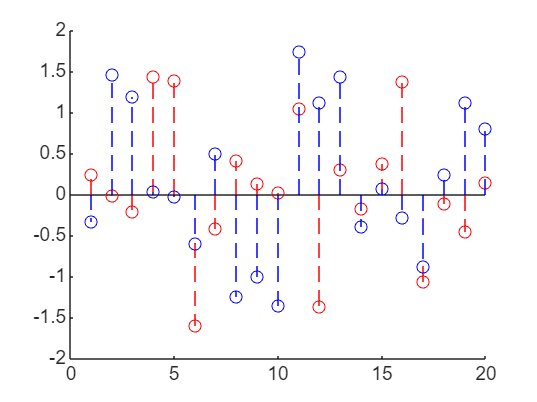

for vec = [xofdm,r1ofdm, r2ofdm]'
    figure ;
    trunc = 20
    vec;
    hold on 
    stem(1:trunc,real(vec(1:trunc)),"r--")
    stem(1:trunc,imag(vec(1:trunc)),"b--")
    hold off
end



a1= [8.1, 2.3, 5, 2.3, 1.9, 0.5];
norm_fac_1 = 1/10.2424;

a2 = [8.1, 2.3, 5, 2.3, 1.9, 0.5, 3, 1.1, 0.9, 0.35, 1.5, 2, 3];
norm_fac_2 = 1/11.4648;

figure
Nk = 100

Nk = 100

h1 = ifft(a1,Nk)

h1 =    0.2010 + 0.0000i   0.1993 + 0.0183i   0.1943 + 0.0359i   0.1863 + 0.0521i   0.1756 + 0.0663i   0.1627 + 0.0782i   0.1483 + 0.0872i   0.1329 + 0.0933i   0.1173 + 0.0964i   0.1020 + 0.0966i   0.0876 + 0.0941i   0.0746 + 0.0894i   0.0633 + 0.0828i   0.0541 + 0.0749i   0.0469 + 0.0662i   0.0418 + 0.0571i   0.0387 + 0.0481i   0.0372 + 0.0397i   0.0371 + 0.0320i   0.0382 + 0.0253i   0.0399 + 0.0197i   0.0421 + 0.0151i   0.0444 + 0.0115i   0.0466 + 0.0088i   0.0485 + 0.0067i   0.0500 + 0.0050i   0.0511 + 0.0036i   0.0519 + 0.0022i   0.0523 + 0.0007i   0.0526 - 0.0010i   0.0529 - 0.0030i   0.0533 - 0.0052i   0.0540 - 0.0077i   0.0551 - 0.0104i   0.0565 - 0.0131i   0.0585 - 0.0157i   0.0610 - 0.0181i   0.0639 - 0.0201i   0.0672 - 0.0218i   0.0708 - 0.0228i   0.0746 - 0.0233i   0.0784 - 0.0232i   0.0821 - 0.0224i   0.0857 - 0.0211i   0.0890 - 0.0192i   0.0919 - 0.0167i   0.0944 - 0.0139i   0.0964 - 0.0107i   0.0978 - 0.0073i   0.0987 - 0.0037i


h2 = ifft(a2,Nk)

h2 =    0.3195 + 0.0000i   0.2974 + 0.0823i   0.2398 + 0.1395i   0.1685 + 0.1573i   0.1089 + 0.1379i   0.0781 + 0.0982i   0.0787 + 0.0607i   0.0988 + 0.0431i   0.1191 + 0.0503i   0.1234 + 0.0734i   0.1060 + 0.0957i   0.0743 + 0.1021i   0.0436 + 0.0869i   0.0288 + 0.0566i   0.0360 + 0.0258i   0.0598 + 0.0095i   0.0862 + 0.0151i   0.0999 + 0.0386i   0.0924 + 0.0669i   0.0656 + 0.0849i   0.0310 + 0.0827i   0.0033 + 0.0604i  -0.0070 + 0.0273i   0.0018 - 0.0032i   0.0226 - 0.0208i   0.0440 - 0.0225i   0.0564 - 0.0138i   0.0570 - 0.0043i   0.0503 - 0.0021i   0.0448 - 0.0094i   0.0473 - 0.0217i   0.0593 - 0.0309i   0.0760 - 0.0305i   0.0892 - 0.0193i   0.0921 - 0.0023i   0.0832 + 0.0120i   0.0674 + 0.0166i   0.0529 + 0.0096i   0.0466 - 0.0049i   0.0508 - 0.0191i   0.0617 - 0.0264i   0.0724 - 0.0251i   0.0766 - 0.0187i   0.0734 - 0.0143i   0.0669 - 0.0176i   0.0649 - 0.0291i   0.0734 - 0.0437i   0.0933 - 0.0526i   0.1188 - 0.0484i   0.1402 - 0.0291i


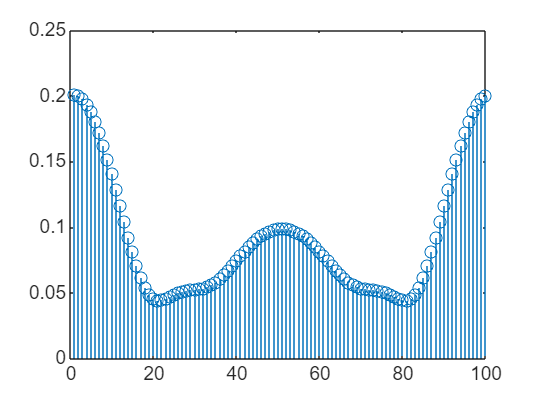

stem(1:Nk,abs(h1))

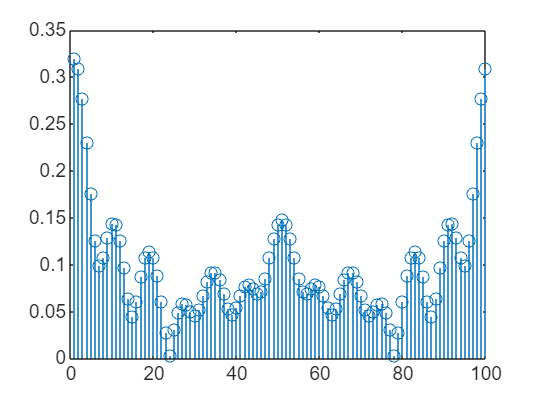

stem(1:Nk,abs(h2))

r1_rec = OFDM_Demod(r1ofdm, Nsc, Ncp, constellation, 1);
r2_rec = OFDM_Demod(r2ofdm, Nsc, Ncp, constellation, 2);

% --- TRUNCATE HERE ---
r1_rec = r1_rec(1:Nbit); 
r2_rec = r2_rec(1:Nbit);

% Calculate Bit Error Rate (BER)
BER1 = sum(abs(bit_stream - r1_rec)) / Nbit

BER1 = 0.0100

BER2 = sum(abs(bit_stream - r2_rec)) / Nbit

BER2 = 0.0300

%% OFDM Performance Evaluation Script
clear; close all; clc;

% --- 1. System Parameters ---
Nsc = 128;           % Number of subcarriers (Standard value, adjust if needed)
Ncp = 16;           % Cyclic Prefix length (Standard value, adjust if needed)
N_OFDM_Syms = 10000;% Number of OFDM symbols per iteration (from Sec 2.2.5)
EbN0_dB = -10:2:20; % Eb/N0 range in dB (from Sec 2.2.6)

% Constellation settings
constellations = {'BPSK', '4QAM', '8QAM'};
bits_per_symbol = [1, 2, 3]; % log2(M) for BPSK, 4QAM, 8QAM

% Pre-allocate BER storage
% Rows: Different constellations, Cols: Different Eb/N0 values
BER_Ch1 = zeros(length(constellations), length(EbN0_dB));
BER_Ch2 = zeros(length(constellations), length(EbN0_dB)); 

%% --- 2. Simulation Loop ---

fprintf('Starting Simulation...\n');

Starting Simulation...



for c_idx = 1:length(constellations)
    current_const = constellations{c_idx};
    M = 2^bits_per_symbol(c_idx); % Constellation order
    k = bits_per_symbol(c_idx);   % Bits per subcarrier
    
    Nbits_total = N_OFDM_Syms * Nsc * k;
    fprintf('Testing %s (%d bits)... ', current_const, Nbits_total);
    
    bit_stream = rand(1, Nbits_total) > 0.5; 
    xofdm = OFDM_Mod(bit_stream, Nsc, Ncp, current_const);
    sig_power = mean(abs(xofdm).^2); 
    
    for snr_idx = 1:length(EbN0_dB)
        ebn0_lin = 10^(EbN0_dB(snr_idx)/10);
        N0 = sig_power / (ebn0_lin * k);

        [r1ofdm, r2ofdm] = Wireless_Channel(xofdm, N0);

        rx_bits_1 = OFDM_Demod(r1ofdm, Nsc, Ncp, current_const, 1);
        
        rx_bits_1 = rx_bits_1(1:Nbits_total);
        
        num_err_1 = sum(abs(bit_stream - rx_bits_1));
        BER_Ch1(c_idx, snr_idx) = num_err_1 / Nbits_total;
        
        if strcmp(current_const, 'BPSK') || strcmp(current_const, '4QAM')

            rx_bits_2 = OFDM_Demod(r2ofdm, Nsc, Ncp, current_const, 2);
            rx_bits_2 = rx_bits_2(1:Nbits_total); % Truncate
            
            num_err_2 = sum(abs(bit_stream - rx_bits_2));
            BER_Ch2(c_idx, snr_idx) = num_err_2 / Nbits_total;
        end
    end
    fprintf('Done.\n');
end

Testing BPSK (1280000 bits)... 

Done.


Testing 4QAM (2560000 bits)... 

Done.


Testing 8QAM (3840000 bits)... 

Done.


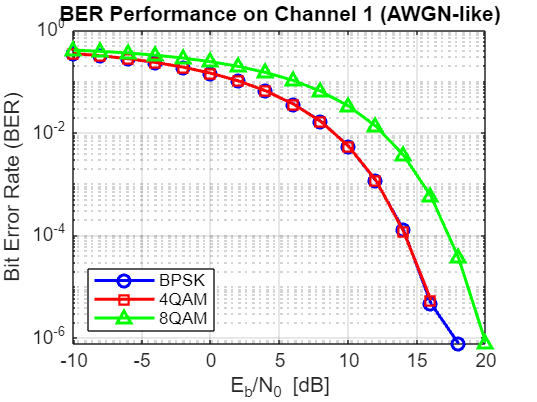

figure('Name', 'BER vs Eb/N0 - Channel 1');
semilogy(EbN0_dB, BER_Ch1(1, :), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'BPSK');
hold on;
semilogy(EbN0_dB, BER_Ch1(2, :), 'r-s', 'LineWidth', 1.5, 'DisplayName', '4QAM');
semilogy(EbN0_dB, BER_Ch1(3, :), 'g-^', 'LineWidth', 1.5, 'DisplayName', '8QAM');
grid on;
xlabel('E_b/N_0 [dB]');
ylabel('Bit Error Rate (BER)');
title('BER Performance on Channel 1 (AWGN-like)');
legend('Location', 'southwest');

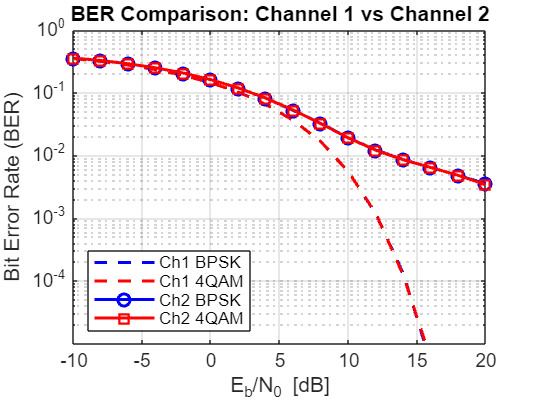



% -- Plot 2: Channel 1 vs Channel 2 (Sec 2.2.8) --
figure('Name', 'Channel 1 vs Channel 2 Performance');
% Channel 1 Curves (Dashed)
semilogy(EbN0_dB, BER_Ch1(1, :), 'b--', 'LineWidth', 1.5, 'DisplayName', 'Ch1 BPSK');
hold on;
semilogy(EbN0_dB, BER_Ch1(2, :), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Ch1 4QAM');

% Channel 2 Curves (Solid)
semilogy(EbN0_dB, BER_Ch2(1, :), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Ch2 BPSK');
semilogy(EbN0_dB, BER_Ch2(2, :), 'r-s', 'LineWidth', 1.5, 'DisplayName', 'Ch2 4QAM');

grid on;
xlabel('E_b/N_0 [dB]');
ylabel('Bit Error Rate (BER)');
title('BER Comparison: Channel 1 vs Channel 2');
legend('Location', 'southwest');
ylim([1e-5 1]); % Set limit to see floor clearly if present
hold off